# PRACTICA 3 - MIMO: estimación de capacidad

#### Maria José Medina y Teresa González

close all
clear
format compact

## 1. Introducción

El objetivo de la práctica es entender el funcionamiento de los sistemas de multiplexación especial basados en MIMO (4x4), evaluar su capacidad, y compararla con la obtenida en un sistema de referencia (SISO, 1x1). 

Para ello, se simularán tanto el caso ideal como el de error de estimación del canal en recepción y se analizarán las diferencias de capacidad para diferentes valores de error en módulo y fase de la matriz de transmisión H.

Además, para ambos casos, se analizarán las diferencias en el comportamiento del sistema MIMO en función de la longitud del prefijo cíclico, el cual sirve para mitigar el efecto de dispersión multritrayecto en la modulación OFDM. Sin embargo, en este laboratorio no se estudiarán los efectos beneficiosos de la ecualización , sino que se utilizará dicho prefijo para incluir un error de fase proporcional a este en la matriz de transmisión, consiguiendo un retardo o desfase adicional entre caminos de propagación, ya que las comunicaciones móviles son multitrayecto y con dispersión elevada por definición.

## 2. Sistema de referencia

Para evaluar el rendimiento del sistema MIMO, se utilizará de referencia la capacidad de un enlace SISO, el cual se compone de una antena transmisora y una antena receptora. Se calculará esta capacidad mediante la ley de Shannon con 1 dB de margen. La potencia transmitida será de 1W (0dB) y el desvanecimiento del canal se estimará como un valor aleatorio en el margen [-6 , 0] dB, con probabilidad de distribución uniforme. Puesto que es un valor aleatorio, será necesario calcular la capacidad como la media de cien iteraciones para cada SNR. 

Para facilitar los cálculos, se especificará la SNR en recepción ya que permite obviar los valores absolutos de potencia. En este valor van comprendidos por tanto tanto la potencia transmitida, como el ruido del canal y el ruido térmico de la siguiente manera:


$$P_{tx} – L = SNR_{rx} + N$$
       

Por tanto, se estudiará la capacidad para distintos valores de $SNR_{rx}$, en particular para el rango [0, 30] dB.

Por último, como se ha explicado en el párrafo anterior, será necesario tener en cuenta el desvanecimiento del canal y el aproximamiento a 1dB del límite de Shannon. En consecuencia, la SNR utilizada para calcular la capacidad en cada iteración será:


$$SNR_{real} = SNR_{rx} - h_{db} - 1$$


Y, por tanto, la capacidad resultante se calcula como:


$$C = log_{2}(1 +SNR_{real})$$


En el siguiente bloque se calculan las capacidades para SNR recibidas en el rango 0 a 30 dB y se representan gráficamente.

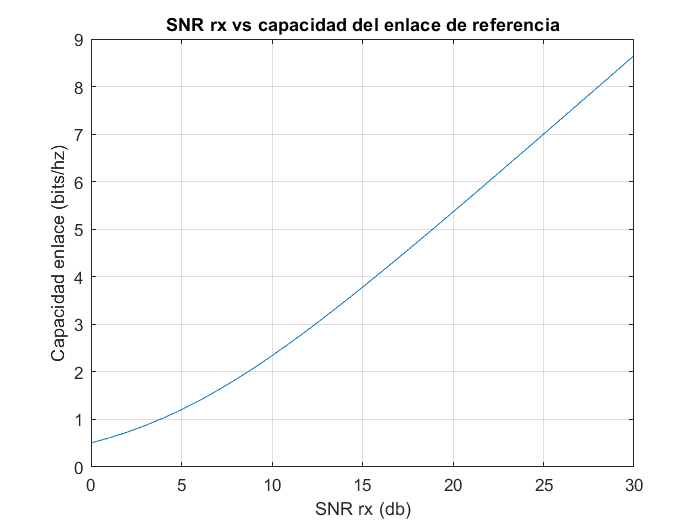

% Definición de parámetros del sistema
BW=1;
Po_tx=0;
SNR_rx= 0:30;

% Matriz h canal en db aleatoria entre -6 y 6 db
h_db=-rand(1,100)*6;

% Inicializar vector de capacidades
c=zeros(1,length(SNR_rx));

% Bucle SNR_rx para calcular la capacidad en función de la SNR
for k=1:length(SNR_rx)
    SNR_iter=SNR_rx(k);
    % Cálculo SNR real en db con degradacion adicional 1 db de SNR limite de Shannon, por lo que disminuye la capacidad
    SNR_real_db= SNR_iter + h_db - 1;
    % Unidades naturales
    SNR_real=10.^((SNR_real_db/10));
    
    %Fórmula capacidad
    c=log2(1+ SNR_real);
    
    %Media de la capacidad
    c_mean_siso(k)=mean(c);
end

% Representación gráfica
plot(SNR_rx, c_mean_siso)
grid on
title ("SNR rx vs capacidad del enlace de referencia")
xlabel("SNR rx (db)")
ylabel("Capacidad enlace (bits/hz)")

A la vista del gráfico, se concluye que la capacidad y la SNR se relacionan de forma exponencial, alcanzando, por ejemplo, un valor de 3.8 bits/Hz para una SNR de 15 db, o un valor máximo de 8.7 bits/Hz para una SNR de 30 dB. Por tanto, a mayor SNR mayor capacidad, así que para alcanzar una capacidad considerable, es necesario transmitir una señal con una potencia lo suficientemente alta. 

## 3 y 4. Sistema MIMO ideal con CP normal y extendido

A continuación se simulará un sistema MIMO ideal con 4 antenas transmisoras y 4 antenas receptoras (16 parejas Tx-Rx).  

La potencia total transmitida (0db) se reparte por igual entre las 4 antenas transmisoras ($– 10\cdot log(Ni) (dB)$ en cada una). El fundamento de la multiplexación espacial es, que en un conjunto de antenas, a cada una se le inyecta la misma señal pero con amplitudes y fases diferentes, independientes, conformando un haz espacial. De esta manera, se atenúa el efecto de la transmisión multitrayecto puetso que se aprovechan los distintos caminos por los que se propaga la señal. Para ello, se estima la respuesta en frecuencia del canal y se representa mediante la matriz H, de dimensiones Ni x No (4x4). Esta matriz representa los 16 modos de la transmisión, es decir, el efecto de cada una de las 16 combinaciones de antentas transmisora y receptora. Puesto que se trabaja en este caso de forma ideal, **el extremo receptor estima correctamente los coeficientes complejos de H, a partir de las señales de referencia o pilotos.**

Debido a la elevada dispersión de las comunicaciones móviles, cada modo llegará con un retardo o dispersión diferente. El caso óptimo tiene lugar cuando todos los modos son iguales, por lo que la potencia transmitida se repartiría por igual entre todos los modos y el peor caso tendrá lugar cuando toda la potencia se transmita tan sólo por un par de antenas, es decir, cuando exista visión directa.

En este sistema, existe en cada cabeza receptora el mismo fondo de ruido que en el sistema de referencia ($SNR_{rx}$), la modulación utilizada es OFDM con una separación entre portadoras de $\Delta f=15 Khz$, y el ancho de banda es igual a la unidad. Además, el canal se modela con la misma atenuación L que en el sistema SISO de referencia.

 Además, para añadir el desfase en la matriz H se utilizarán las longitudes de prefijo cíclico estándar y extendido para LTE. Este último, aunque no se suele utilizar para comunicaciones 4G o 5G, sí se suele utilizar para la transmisión WiFi debido a la alta dispersión que presenta. En el caso del prefijo estándar, se ha calculado el valor de su longitud con la media ponderada entre la utilizada para el primer símbolo (160) y la utilizada para los 6 restantes (144), quedando en 146. Para el prefijo extendido, se ha utilizado la longitud de 512. Para simular el canal, se va a generar la matriz H con desvanecimientos aleatorios de 0 a 6 dB de amplitud y un desplazamiento en fase también aleatorio con valor máximo proporcional al ratio entre la longitud del prefijo cíclico y la longitud de la NFFT para LTE (2048). 

Por otro lado, en un sistema MIMO se utiliza un módulo de preprocesado de la señal tanto en transmisión como en recepción. Este módulo fuerza a que por cada antena receptora solo se reciban datos de una única antena transmisora. Esto se consigue mediante la diagonalización de la matriz H de la siguiente forma: 

    
$$Y = U^H\cdot H\cdot V \cdot  X	= D  \cdot  X$$
 

siendo U la matriz de autovectores de $H\cdot H^H$ y V la matriz de autovectores de $H^H\cdot H$ , y $D= U^H \cdot  H \cdot  V$.

Con estas operaciones, ya que es un caso ideal, el extremo receptor combina adecuadamente las señales recibidas, conociendo los coeficientes de H, para que la matriz D sea diagonal, y las señales recibidas (y(i)) para cada modo i se puedan calcular en función de las transmitidas (x(i)) en el puerto correspondiente como $y(i)=d(i) \cdot  x (i) + v(i)$ , siendo d(i) la raíz cuadrada del autovalor i de $H\cdot H^H$, y v(i) el ruido asociado a cada modo. 

Además, la SNR asociada a cada modo i equivale a $(S_i/N) = di^2\cdot |x_i|^2/N$ , siendo Si la potencia de señal del modo y N la potencia de ruido que entrega el conjunto de antenas. Otra forma de calcularlo es:


$$S(i)/N(i) (B) = (S/N)_{ref} (dB) – 10\cdot log(Ni) - 10\cdot log(No) + 10\cdot log(d^2i)	$$


En este caso, también se ha asumido una degradación adicional en la relación SNR de 1 db respecto al límite establecido por la Ley de Shannon.

Se extrae de la ecuación anterior que la calidad de un modo individual es mayor cuanto mayor sea su capacidad de transmisión, es decir, su valor di correspondiente. Si durante la transmisión el di de un modo en concreto es mucho más significativo que el resto, se puede considerar que hay visión directa. Por tanto, la información a transmitir se debería inyectar únicamente en el puerto i, con el autovalor más significativo, ya que inyectarlo en los puertos restantes es inútil, ya que la energía asociada es despreciable. Entonces, en ese puerto i se obtiene la suma coherente (suma de amplitudes) de los caminos de propagación. Sin embargo, el fondo de ruido aumenta respecto al uso de SISO, ya que este se suma de forma incoherente (suma de potencias).

### a) Definición y ejecución de script

En este apartado se define el sistema MIMO, (parámetros, matriz H, ruido, etc), con ambas longitudes de prefijo cíclico, y se calcula la capacidad media a partir de 100 iteraciones, en función de la SNR en recepción (de 0 a 30 db), para atenuar los efectos de las variables aleatorias.

Es importante destacar, que en LTE, cada slot tiene una duración de 0.5 ms y comprende 7 símbolos OFDM con CP normal, o 6 con CP extendido ya que caben menos en el slot porque tienen mayor duración. Esto se debe a que con el CP extendido, tanto el periodo de guarda  como el periodo de símbolo total son mayores. Como se ha explicado antes, el retardo asociado a cada modo se simulará mediante un desplazamiento de fase aleatorio en cada modo de la matriz H de valor máximo proporcional al ratio entre la longitud del prefijo cíclico y la longitud de la FFT.

#### Prefijo cíclico normal

% Nº antenas tx
Ni=4; 
% Nº antenas rx
No=4; 

%Puntos LTE
NFFT=2048; 

%Normal CP media ponderada (l=0 distinto).
Ncp= round((160*1 + 144*6)/7); 

%faseMax, retardo proporcional duracion prefijo ciclico
faseMax= 2*pi*Ncp/NFFT;

%Inicializacion SNRs
SNR_real=0;
SNR_iter=0;
SNR_real_db=0;

%Nº iteraciones bucle
n_iter = 100;

%Bucle SNRS
for k=1:length(SNR_rx)
    %Inicializacion vector capacidad
    c_total = zeros(1,n_iter);
    %Inicializacion vector coeficientes de los modos
    di=zeros(n_iter,No);
    
    %Cálculo SNR
    SNR_iter=SNR_rx(k) - 10*log10(Ni) - 10*log10(No);

    %Bucle iteraciones
    for l=1:n_iter
        %Matriz transmision H random [-6,6] en db
        H_db=-rand(Ni,No)*6;
        %Unidades naturales
        H= 10.^(H_db/20);
        
        %Fase random en función de faseMax
        fase=rand([Ni,No]).*faseMax;

        %Expresion H con modulo y fase en unidades naturales
        H=H.*exp(-i.*fase); 
        
        %Calculos matrices
        H_Htc=H*H';
        Htc_H=H'*H;

        %Autovalores
        [~,D1] = eig(H_Htc); % lo mismo para Htc_H, matriz diagonal
        %Autovalores en db
        D1_db = 10*log10(D1);

        %vector de capacidades 4 modos
        c = zeros(1,No);

        for d=1:No
            %Matriz coeficientes de cada modo
            di(l,d)=sqrt(D1(d,d));
            %SNR real teniendo en cuenta los autovalores y la degradacion adicional 1 db de SNR limite de Shannon
            SNR_real_db= SNR_iter + D1_db(d,d) - 1; 
            %SNR en dbs
            SNR_real=10.^((SNR_real_db/10));
            %Calculo capacidad
            c(d)=log2(1+ SNR_real);
        end
        %Capacidad total suma de los modos
        c_total(l)= sum(c);

    end
    %Media coeficientes de cada modo
    di = mean(di);
    %Media capacidad CP normal
    c_mean_cp(k)=mean(c_total);
end




#### Prefijo cíclico extendido

%Longitud prefijo cíclico extendido
Ncp_ext= 512;

%faseMax proporcional a Ncp ext
faseMax_ext= 2*pi*Ncp_ext/NFFT;

%Inicializar
SNR_real=0;
SNR_iter=0;
SNR_real_db=0;

%Nº iters
n_iter = 100;

%Bucle SNR
for k=1:length(SNR_rx)
    c_total = zeros(1,n_iter);
    %Matriz para los coeficientes de cada modo
    di_ext=zeros(n_iter,No);
    SNR_iter=SNR_rx(k) - 10*log10(Ni) - 10*log10(No);

    for l=1:n_iter
        H_db=-rand(Ni,No)*6;
        H= 10.^(H_db/20);
        fase=rand([Ni,No]).*faseMax_ext;

        H=H.*exp(-i.*fase); %unidades naturales
        H_Htc=H*H';
        Htc_H=H'*H;

        %autovalores
        [~,D1] = eig(H_Htc); % lo mismo para Htc_H porque la matriz D es diagonal
        D1_db = 10*log10(D1);

        %4 modos
        c = zeros(1,No);

        for d=1:No
            di_ext(l,d)=sqrt(D1(d,d)); %rellenar matriz de coeficientes con la raiz de los autovalores
            SNR_real_db= SNR_iter + D1_db(d,d) - 1; %degradacion adicional 1 db de SNR limite de Shannon, disminuye la capacidad
            SNR_real=10.^((SNR_real_db/10));
            c(d)=log2(1+ SNR_real);
        end
        c_total(l)= sum(c);

    end
    di_ext = mean(di_ext);
    c_mean_cp_ext(k)=mean(c_total);

end




### b y c) Gráficas y análisis de resultados

En este apartado se representan sobre una misma gráfica las capacidades en bits/Hz obtenidas para el sistema SISO, MIMO 4x4 con CP normal y MIMO 4X4 con CP extendido, en función de la SNR de referencia en recepción, y se lleva a cabo una comparación entre ellas.

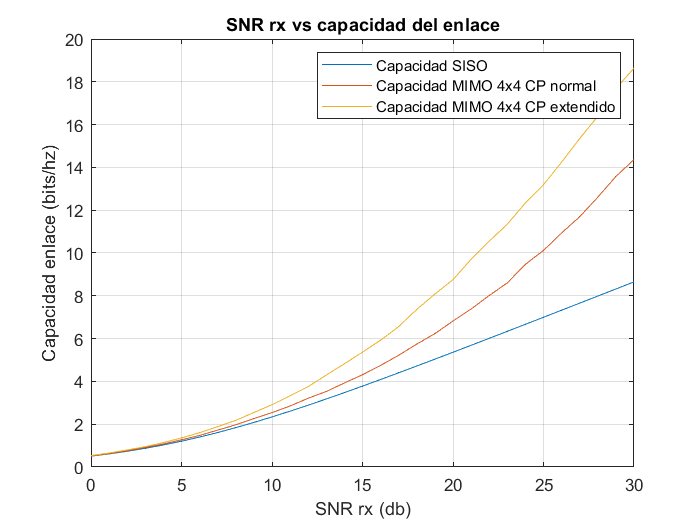

% Representacion
figure
plot(SNR_rx, c_mean_siso)
hold on
plot(SNR_rx, c_mean_cp)
hold on
plot(SNR_rx, c_mean_cp_ext)
grid on
title ("SNR rx vs capacidad del enlace")
xlabel("SNR rx (db)")
ylabel("Capacidad enlace (bits/hz)")
legend("Capacidad SISO", "Capacidad MIMO 4x4 CP normal", "Capacidad MIMO 4x4 CP extendido")

Como se puede observar en la figura anterior, la capacidad del enlace aumenta en todos los casos con la SNR en recepción, como es de esperar. Destaca también que aumenta considerablemente con el uso de MIMO, especialmente para el caso de prefijo cíclico extendido. En particular, para una SNR de 30 dB se obtienen unas capacidades de:

- 8.59 [bits/Hz] para el caso SISO

- 14.38 [bits/Hz] para el caso CP normal

- 18.42 [bits/Hz] para el caso CP extendido

Por lo tanto, se concluye que el uso de MIMO mejora la capacidad de los enlaces de comunicaciones.  Por otro lado, puesto que la simulación usando un CP extendido es la que cuenta con la mayor capacidad mientras que también presenta el mayor desplazamiento de fase, se puede confirmar que el sistema MIMO es más eficiente en presencia de distorsión multitrayecto. Como se explicaba anteriormente, esto se debe a que la señal de forma más uniforme por los diferentes modos.

### d) Análisis de los valores de di

Para analizar los coeficientes di de cada modo, se realiza una comparación para los dos casos de longitud de CP y para una SNR de 30 dB.  Para ello se calcula la media de los valores de di para cada modo, como la raíz cuadrada de los autovalores obtenidos, y se hace la media, tanto para CP normal como CP extendido.

Se representan los di de cada modo en un diagrama de barras:

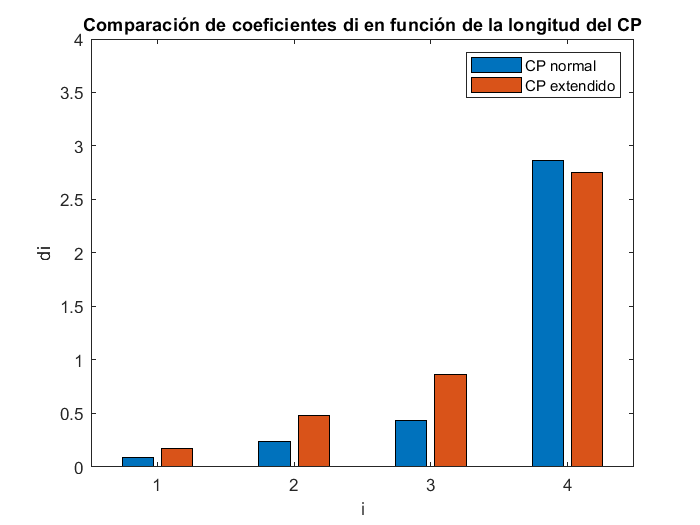

figure
bar([di;di_ext]')
title ("Comparación de coeficientes di en función de la longitud del CP")
xlabel("i")
ylabel("di")
ylim([0 4])
legend("CP normal", "CP extendido")

En ambos casos, el valor $d_4$ es significativamente mayor que el resto de valores. Esto significa que la mayor parte de la transmisión se realiza por un único par de atenas porque la visión es bastante directa. Sin embargo, para el caso del CP extendido, el valor de $d_4$ es menor que para el caso del CP normal y el resto de $d_i$ son mayores. Esto se debe a que presenta mayor dispersión, por lo que es más eficiente utilizar varios trayectos de la señal para aumentar la capacidad. Como se ha explicado antes, cuanto más repartida esté la energía entre los distintos modos (cuanto más parecidos sean los los valores de $d_i$), mejor será la comunicación MIMO. Un $d_i$ próximo a 4 indica que en el puerto de salida i lo que se obtiene es la suma coherente de los caminos de propagación. Eso sí, con un aumento de 3 dB del fondo de ruido, porque el ruido de entrada a las dos antenas se suma de forma incoherente. 

Cuantitativamente, para un valor de SNR de 30 dB, se obtiene:

- Para CP normal,$\Delta fase_{max}$ =  0.45, $d_4$ = 2.9 dB y C = 14,38 bits/Hz

- Para CP extendido, $\Delta fase_{max}$ =  1,57, $d_4$ = 2.76 dB y C = 18,42 bits/Hz

Por tanto, una diferencia de 1,12 radianes de desplazamiento de fase produce 4 bits/Hz más de capacidad.

## 5 y 6. Sistema MIMO con errores de estimación de canal

En la segunda parte de la práctica ya no se contempla el caso ideal, en el que las cabezas receptoras estiman correctamente los coeficientes de la matriz de transmisión H. Se introducen errores en dichos coeficientes tanto en módulo como en fase, y se analiza el impacto en la capacidad obtenida, tanto en el caso de CP normal como CP extendido. 

Debido a los errores de estimación, la matriz D ya no es diagonal, por lo que lo que se envía por una antena transmisora no es recibido tan solo por una antena receptora, sino que existen intereferencias. En cada puerto i de salida se obtiene, además del ruido de fondo total y una réplica de la señal del puerto de entrada i, un ruido extra, interferente, llamado ruido de diafonía, que proviene de manera indeseada de los otros puertos de entrada j, j≠i (que corresponderían a otros modos). Por ello, al calcular la relación SNR del modo i, se debe tener en cuenta que algo de la potencia inyectada en el puerto de entrada i se pierde, ya que se desvía o se cuela en otros puertos de salida j, y además en el puerto de salida i correspondiente aparece el ruido de diafonía, que proviene de la potencia de entrada de otros puertos que se han colado en recepción.

Para simular el error de estimación de la matriz H, se generará una matriz $h_{err}$ cuyos coeficientes vendrán determinados por:


$$|h_{ij,err|} (dB) = |h_{ij}| (dB)  - \Delta mod (dB)$$



$$fase (h_{ij,err})  = fase (h_{ij}) + \Delta fase$$


Donde $h_{ij}$ es el elemento (i,j) de matriz H sin errores, y  Δmod y  Δfase son variables aleatorias con una distribución uniforme que se puede asumir uniforme centrada en 0:


$$\Delta mod = rand[-\Delta modMax,  \Delta modMax]$$



$$\Delta fase = rand[-\Delta faseMax,  \Delta faseMax]
$$


Como resultado de este error en la estimación, la capacidad obtenida cae bruscamente. Para calcular dicha capacidad, se calcula de nuevo la media, esta vez de 1000 iteraciones, para contrarrestar el carácter aleatorio del error en la estimación del canal. 

### Prefijo cíclico normal

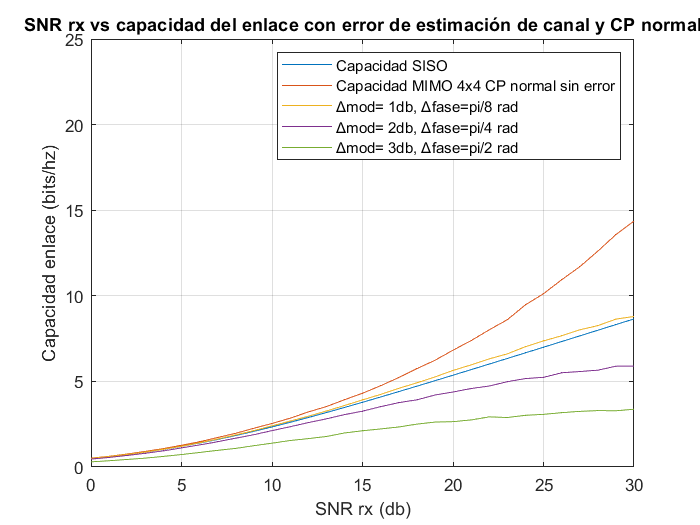

%Definicion de valores máximos 
delta_mod_max= [1 2 3]; %db
delta_fase_max= [pi/8 pi/4 pi/2]; %rad


Ni=4; %tx
No=4; %rx

NFFT=2048; %LTE

%con prefijo normal
Ncp= round((160*1 + 144*6)/7); %Normal CP media ponderada (l=0 distinto). el que + se usa
faseMax= 2*pi*Ncp/NFFT;

%Inicializaciones
SNR_real=0;
SNR_iter=0;
SNR_real_db=0;

%Número iteraciones
n_iter = 1000;

%Matriz con errores estimación
Herr=zeros(Ni,No);


%BUCLE
for m=1:length(delta_mod_max)
    for k=1:length(SNR_rx)
        c_total = zeros(1,n_iter);


        for l=1:n_iter
            %Matriz H random entre -6 y 6 db
            H_db=-rand(Ni,No)*6;
            
            H= 10.^(H_db/20);
            fase=rand([Ni,No]).*faseMax;

            H=H.*exp(-i.*fase); %unidades naturales
            
            %Relleno de Herr a partir de H, con error en módulo y fase
            %adicional
            Herr= create_error(H, delta_mod_max(m), delta_fase_max(m));
           

            %matrices
            [Uerr, ~]=eig(Herr*Herr');
            [Verr,~]=eig(Herr'*Herr);
            
            %Matriz D
            D= Uerr'*H*Verr; %ya no es diagonal, como ocurre en el caso ideal.
            %Ptx repartida en antenas Tx (db)
            P_db=-10*log10(Ni);
            %Ptx en unidades naturales
            P=10^(P_db/10);
            
            %matrix P mismos puertos
            X = eye(Ni)*(P^(1/2));

            %señal recibida
            Y=D*X;

            %potencia de la señal
            S=(abs(Y)).^2;
            S_db=10*log10(S);


            %Ruido total = ruido termico + ruido interferencias
            N_termico_db= -SNR_rx(k) +10*log10(No);
            N_termico= 10^(N_termico_db/10);

            %N interferencias la P en distintos puertos
            X_int= (ones(Ni)-eye(Ni))*(P^(1/2));
            Y_int=D*X_int;
            N_int=(abs(Y_int)).^2;
            N= N_termico + N_int;

            SNR_iter= S./N;
            SNR_iter_db=10*log10(SNR_iter);

            %4 modos
            c = zeros(1,No);

            for d=1:No
                SNR_real_db= SNR_iter_db(d,d) - 1; %degradacion adicional 1 db de SNR limite de Shannon, disminuye la capacidad
                SNR_real=10.^((SNR_real_db/10));
                c(d)=log2(1+ SNR_real);
            end
            c_total(l)= sum(c);

        end

        c_mean_cp_err(m,k)=mean(c_total);
    end

end


%GRAFICAS CP NORMAL
figure
plot(SNR_rx, c_mean_siso)
hold on
plot(SNR_rx, c_mean_cp)
hold on
plot(SNR_rx, c_mean_cp_err)

grid on
ylim([0 25])
title ("SNR rx vs capacidad del enlace con error de estimación de canal y CP normal")
xlabel("SNR rx (db)")
ylabel("Capacidad enlace (bits/hz)")
legend("Capacidad SISO", "Capacidad MIMO 4x4 CP normal sin error", "Δmod= 1db, Δfase=pi/8 rad", "Δmod= 2db, Δfase=pi/4 rad", "Δmod= 3db, Δfase=pi/2 rad")

Como se puede observar en la figura anterior, la capacidad del enlace sigue aumentando en todos los casos con la SNR en recepción. Sin embargo, la capacidad MIMO disminuye significativamente con el error en la estimación de H, quedando igual que la capacidad SISO para el caso $\Delta mod$ = 1 dB y $\Delta fase$ = $\frac{\pi}{8} [rad]$ y llegando a ser 2.7 [bits/Hz] menor que la SISO en el caso de $\Delta mod$ = 2 dB y $\Delta fase$ = $\frac{\pi}{8} [rad]$; y  5.4 [bits/Hz] menor en el caso de $\Delta mod$ = 3 dB y $\Delta fase$ = $\frac{\pi}{4} [rad]$. Además, para este último caso, la capacidad se estanca a pesar del aumento en SNR. Cuantitativamente, para una SNR de 30 dB se obtienen unas capacidades de:

- 8.7 [bits/Hz] para el caso SISO

- 14.38 [bits/Hz] para el caso CP normal sin error

- 8.7 [bits/Hz]  para el caso $\Delta mod$ = 1 dB y $\Delta fase$ = $\frac{\pi}{8} [rad]$

- 6.05 [bits/Hz] para el caso $\Delta mod$ = 2 dB y $\Delta fase$ = $\frac{\pi}{4} [rad]$

- 3.33 [bits/Hz] para el caso $\Delta mod$ = 3 dB y $\Delta fase$ = $\frac{\pi}{2} [rad]$

Por lo tanto, se concluye que un pequeño error en la estimación del canal empeora considerablemente la capacidad de los enlaces de comunicaciones y para un error mayor estanca la capacidad y causa que esta no aumente por mucho que aumente la SNR. Por tanto, es un grave problema de las comunicaciones MIMO la necesidad de que en ambos extremos se conozca la matriz H y obliga a enviar señales de referencia constantemente, con un periodo de variación inferior al tiempo de variación del canal, el cual suele ser del orden de milisegundos. Además, por cada realimentación se debe calcular una matriz nueva de precodificación, lo cual implica un overhead computacional. En consecuencia, es común disponer de un conjunto de matrices de precodificación predefinidas y elegir de entre ellas la que mejor se adapte a la situación del canal.

### Prefijo cíclico extendido

A continuación se repite el apartado anterior para un prefijo cíclico extendido. Este script difiere del anterior en el valor de faseMax, así como del desfase en los coeficientes de la matriz H, y como consecuencia de Herr.

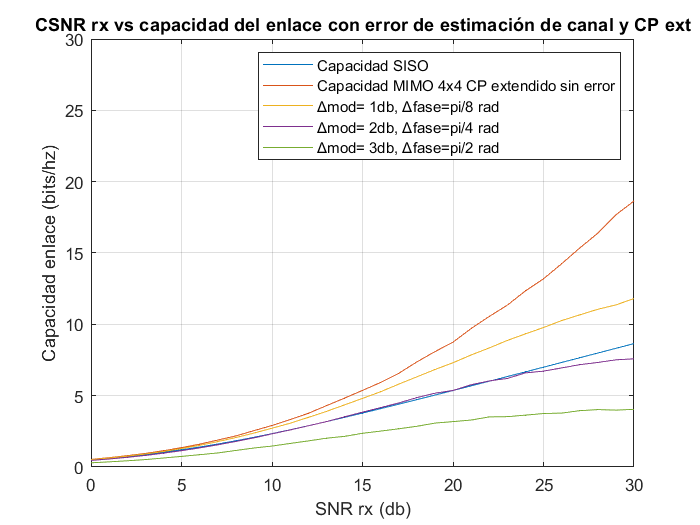

%CON PREFIJO EXTENDIDO
Ncp_ext= 512;
faseMax_ext= 2*pi*Ncp_ext/NFFT;


SNR_real=0;
SNR_iter=0;
SNR_real_db=0;

SNR_real=0;
SNR_iter=0;
SNR_real_db=0;

n_iter = 1000;

Herr=zeros(Ni,No);


%BUCLE
for m=1:length(delta_mod_max)
    for k=1:length(SNR_rx)
        c_total = zeros(1,n_iter);


        for l=1:n_iter
            H_db=-rand(Ni,No)*6;

            H= 10.^(H_db/20);
            fase=rand([Ni,No]).*faseMax_ext;

            H=H.*exp(-i.*fase); %unidades naturales
            Herr= create_error(H, delta_mod_max(m), delta_fase_max(m));
            % Herr= create_error(H, 10^((delta_mod_max(m)/20)), delta_fase_max(m));

            %matrices
            [Uerr, ~]=eig(Herr*Herr');
            [Verr,~]=eig(Herr'*Herr);

            D= Uerr'*H*Verr; %ya no es diagonal, como ocurre en el caso ideal.

            P_db=-10*log10(Ni);
            P=10^(P_db/10);
            %P mismos puertos
            X = eye(Ni)*(P^(1/2));

            %señal recibida
            Y=D*X;

            %potencia de la señal
            S=(abs(Y)).^2;
            S_db=10*log10(S);


            %ruido total = ruido termico + ruido interferencias
            N_termico_db= -SNR_rx(k) +10*log10(No);
            N_termico= 10^(N_termico_db/10);

            %N interferencias la P en distintos puertos
            X_int= (ones(Ni)-eye(Ni))*(P^(1/2));
            Y_int=D*X_int;
            N_int=(abs(Y_int)).^2;
            N= N_termico + N_int;

            SNR_iter= S./N;
            SNR_iter_db=10*log10(SNR_iter);

            %4 modos
            c = zeros(1,No);

            for d=1:No
                SNR_real_db= SNR_iter_db(d,d) - 1; %degradacion adicional 1 db de SNR limite de Shannon, disminuye la capacidad
                SNR_real=10.^((SNR_real_db/10));
                c(d)=log2(1+ SNR_real);
            end
            c_total(l)= sum(c);

        end

        c_mean_cp_err_ext(m,k)=mean(c_total);
    end

end


%GRAFICAS CP EXTENDIDO
figure
plot(SNR_rx, c_mean_siso)
hold on
plot(SNR_rx, c_mean_cp_ext)
hold on
plot(SNR_rx, c_mean_cp_err_ext)
grid on
ylim([0 30])
title ("CSNR rx vs capacidad del enlace con error de estimación de canal y CP ext")
xlabel("SNR rx (db)")
ylabel("Capacidad enlace (bits/hz)")
legend("Capacidad SISO", "Capacidad MIMO 4x4 CP extendido sin error", "Δmod= 1db, Δfase=pi/8 rad", "Δmod= 2db, Δfase=pi/4 rad", "Δmod= 3db, Δfase=pi/2 rad" )

Como se puede observar en la figura anterior, la capacidad del enlace sigue aumentando en todos los casos con la SNR en recepción. Sin embargo, la capacidad MIMO vuelve  a disminuir significativamente con el error en la estimación de H, aunque mejora respecto al caso del prefijo cíclico normal. Cuantitativamente, para una SNR de 30 dB se obtienen unas capacidades de:

- 8.7 [bits/Hz] para el caso SISO

- 14.38 [bits/Hz] para el caso CP normal sin error

- 11.8 [bits/Hz]  para el caso $\Delta mod$ = 1 dB y $\Delta fase$ = $\frac{\pi}{8} [rad]$

- 7.6 [bits/Hz] para el caso $\Delta mod$ = 2 dB y $\Delta fase$ = $\frac{\pi}{4} [rad]$

- 4.04 [bits/Hz] para el caso $\Delta mod$ = 3 dB y $\Delta fase$ = $\frac{\pi}{2} [rad]$

Por tanto, de nuevo se comprueba que MIMO funciona mejor con mayor dsipersión, tal y como se comentaba en el apartado anterior. Sin embargo, de nuevo, el error de estimación disminuye considerablemente la capacidad.

### EXTRA: Análisis de la degradación de la capacidad por error en módulo y en fase de forma aislada

En este apartado se analizará la pérdida de capacidad debido al error en módulo y fase en los coeficientes de H por separado. Se utilizará un CP normal. Se comentarán los resultados al final del apartado de forma conjunta.

#### Error en módulo

Se repite el mismo proceso que en los scripts anteriores incluyendo solamente un error en módulo.

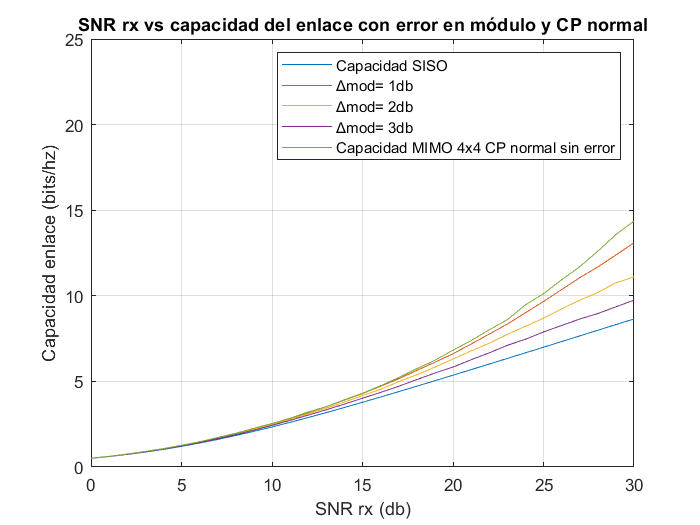


%GRAFICAS CP normal con error en mod

Ncp= round((160*1 + 144*6)/7); %Normal CP media ponderada (l=0 distinto). el que + se usa
faseMax= 2*pi*Ncp/NFFT;

SNR_real=0;
SNR_iter=0;
SNR_real_db=0;

n_iter = 1000;

Herr=zeros(Ni,No);


%BUCLE
for m=1:length(delta_mod_max)
    for k=1:length(SNR_rx)
        c_total = zeros(1,n_iter);


        for l=1:n_iter
            H_db=-rand(Ni,No)*6;

            H= 10.^(H_db/20);
            fase=rand([Ni,No]).*faseMax;

            H=H.*exp(-i.*fase); %unidades naturales
            Herr= create_error(H, delta_mod_max(m), 0);
            % Herr= create_error(H, 10^((delta_mod_max(m)/20)), delta_fase_max(m));

            %matrices
            [Uerr, ~]=eig(Herr*Herr');
            [Verr,~]=eig(Herr'*Herr);

            D= Uerr'*H*Verr; %ya no es diagonal, como ocurre en el caso ideal.

            P_db=-10*log10(Ni);
            P=10^(P_db/10);
            %P mismos puertos
            X = eye(Ni)*(P^(1/2));

            %señal recibida
            Y=D*X;

            %potencia de la señal
            S=(abs(Y)).^2;
            S_db=10*log10(S);


            %ruido total = ruido termico + ruido interferencias
            N_termico_db= -SNR_rx(k) +10*log10(No);
            N_termico= 10^(N_termico_db/10);

            %N interferencias la P en distintos puertos
            X_int= (ones(Ni)-eye(Ni))*(P^(1/2));
            Y_int=D*X_int;
            N_int=(abs(Y_int)).^2;
            N= N_termico + N_int;

            SNR_iter= S./N;
            SNR_iter_db=10*log10(SNR_iter);

            %4 modos
            c = zeros(1,No);

            for d=1:No
                SNR_real_db= SNR_iter_db(d,d) - 1; %degradacion adicional 1 db de SNR limite de Shannon, disminuye la capacidad
                SNR_real=10.^((SNR_real_db/10));
                c(d)=log2(1+ SNR_real);
            end
            c_total(l)= sum(c);

        end

        c_mean_err_mod(m,k)=mean(c_total);
    end

end

figure
plot(SNR_rx, c_mean_siso)
hold on
plot(SNR_rx, c_mean_err_mod)
hold on
plot(SNR_rx, c_mean_cp)
grid on
ylim([0 25])
title ("SNR rx vs capacidad del enlace con error en módulo y CP normal")
xlabel("SNR rx (db)")
ylabel("Capacidad enlace (bits/hz)")
legend("Capacidad SISO","Δmod= 1db", "Δmod= 2db", "Δmod= 3db" , "Capacidad MIMO 4x4 CP normal sin error")

#### Error en fase

Se repite el mismo proceso que en los scripts anteriores incluyendo solamente un error en fase.

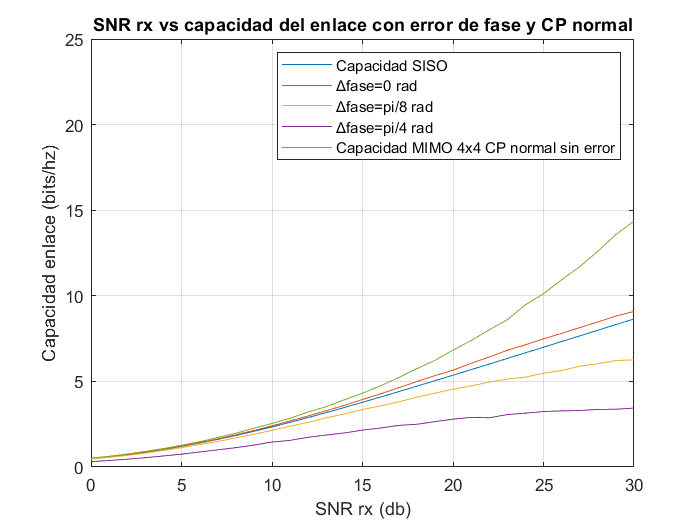

%GRAFICAS CP normal con error en fase

Ncp= round((160*1 + 144*6)/7); %Normal CP media ponderada (l=0 distinto). el que + se usa
faseMax= 2*pi*Ncp/NFFT;

SNR_real=0;
SNR_iter=0;
SNR_real_db=0;

n_iter = 1000;

Herr=zeros(Ni,No);


%BUCLE
for m=1:length(delta_mod_max)
    for k=1:length(SNR_rx)
        c_total = zeros(1,n_iter);


        for l=1:n_iter
            H_db=-rand(Ni,No)*6;

            H= 10.^(H_db/20);
            fase=rand([Ni,No]).*faseMax;

            H=H.*exp(-i.*fase); %unidades naturales
            Herr= create_error(H, 0, delta_fase_max(m));
            % Herr= create_error(H, 10^((delta_mod_max(m)/20)), delta_fase_max(m));

            %matrices
            [Uerr, ~]=eig(Herr*Herr');
            [Verr,~]=eig(Herr'*Herr);

            D= Uerr'*H*Verr; %ya no es diagonal, como ocurre en el caso ideal.

            P_db=-10*log10(Ni);
            P=10^(P_db/10);
            %P mismos puertos
            X = eye(Ni)*(P^(1/2));

            %señal recibida
            Y=D*X;

            %potencia de la señal
            S=(abs(Y)).^2;
            S_db=10*log10(S);


            %ruido total = ruido termico + ruido interferencias
            N_termico_db= -SNR_rx(k) +10*log10(No);
            N_termico= 10^(N_termico_db/10);

            %N interferencias la P en distintos puertos
            X_int= (ones(Ni)-eye(Ni))*(P^(1/2));
            Y_int=D*X_int;
            N_int=(abs(Y_int)).^2;
            N= N_termico + N_int;

            SNR_iter= S./N;
            SNR_iter_db=10*log10(SNR_iter);

            %4 modos
            c = zeros(1,No);

            for d=1:No
                SNR_real_db= SNR_iter_db(d,d) - 1; %degradacion adicional 1 db de SNR limite de Shannon, disminuye la capacidad
                SNR_real=10.^((SNR_real_db/10));
                c(d)=log2(1+ SNR_real);
            end
            c_total(l)= sum(c);

        end

        c_mean_err_fase(m,k)=mean(c_total);
    end

end

figure
plot(SNR_rx, c_mean_siso)
hold on
plot(SNR_rx, c_mean_err_fase)
hold on
plot(SNR_rx, c_mean_cp)
grid on
ylim([0 25])
title ("SNR rx vs capacidad del enlace con error de fase y CP normal")
xlabel("SNR rx (db)")
ylabel("Capacidad enlace (bits/hz)")
legend("Capacidad SISO","Δfase=0 rad", "Δfase=pi/8 rad", "Δfase=pi/4 rad" , "Capacidad MIMO 4x4 CP normal sin error")

Como es de esperar, el sistema MIMO es considerablemente más sensible a errores de fase que a errores en amplitud. Esto es lógico puesto que el sistema tiene en cuenta los diferentes caminos por los que puede llegar una señal, caracterizados por desplazamientos de fase en frecuencia o retardos en tiempo. Por tanto, a la hora de estimar la matriz H, será mucho más relevante estimar correctamente las fases que las amplitudes de los coeficientes.

## Conclusión

En esta práctica se ha estudiado el sistema MIMO, el cual se utiliza para disminuir el efecto de la dispersión multitrayecto en comunicaciones móviles. 

En primer lugar, se han comparado las capacidades de una transmisión SISO con las de MIMO para dos valores de dispersión distintos, caracterizados por la longitud del prefijo cíclico utilizado. Se ha demostrado que la capacidad del sistema MIMO es considerablemete mejor que la de SISO y que la capacidad del sistema mejora con el aumento nivel de dispersión. Por lo tanto, es beneficioso para transmisiones multitrayecto, con un alto grado de dispersión como pueden ser comunicaciones móviles en ciudad o, especialmente, en comunicaciones en interiores como puede ser a través de una red WiFi.

A continuación, se ha estimado la gravedad del error en la estimación del canal en las comunicaciones MIMO mediante una atenuación y un desplazamiento en fase de la respuesta en frecuencia. Se ha concluído que la capacidad se ve claramente afectada por este error de estimación, en especial por el desplazamiento de fase, y que a partir de cierto umbral (en nuestro caso $\Delta mod$ = 3 dB y $\Delta fase$ = $\frac{\pi}{2} [rad]$) la capacidad de veía estancada y dejaba de aumentar con la SNR. Por lo tanto, una correcta estimación del canal es clave para poder aprovechar los beneficios de un sistema MIMO. Sin embargo, puesto que la respuesta al impulso del canal varía en cuestión de milisegundos, esta estimación y el posterior cálculo de los parámetros de los módulos de precodificación suponen un overhead considerable. Por ello, es común utilizar matrices precodificadas estándar y elegir de entre ellas la que mejor se adapte al canal en cada momento.